# Laboratorio: optimización sin restricciones

**Autores (Grupo 4):** Javier Blanco Álvarez, Pablo Castañeda Fuentes, Lucía Royo Pascual, Ferrán Soto Moscardó, Jesús Gallinal Moreno.

**Asignatura: **Optimización

## RESUMEN

En esta práctica se examina la aplicación de métodos de optimización del descenso de gradiente para determinar superficies mínimas de revolución, comparando enfoques de pasos fijos y variables. Se implementaron métodos de Fibonacci y Búsqueda dicotómica para la optimización de pasos, analizando su efectividad para encontrar soluciones óptimas. Partiendo de dos funciones iniciales (una línea recta y una parábola), examinamos el comportamiento de convergencia y la precisión de la solución en diferentes niveles de discretización. Con esta práctica se demuestra la implementación práctica de técnicas de optimización multivariable sin restricciones al tiempo que enfatiza la importancia de la selección adecuada de pasos en problemas de optimización. Los resultados indican la efectividad de los métodos de paso variable para lograr mejores características de convergencia en comparación con los enfoques de paso fijo. 

**Palabras clave:** Optimización sin restricciones, descenso del gradiente, método del trapecio, superficies de revolución, Fibonacci, bñusqueda dicotómica. 

## INTRODUCCIÓN

El estudio de superficies mínimas de revolución mediante la optimización del descenso de gradientes representa una combinación útil y rigurosa entre el cálculo de variaciones y los métodos numéricos. En esta práctica se explora la implementación del descenso de gradiente con tasas de aprendizaje fijas y variables para encontrar la superficie de revolución óptima que minimice el área. El análisis abarca dos condiciones iniciales: una línea recta u(x) = 1 y una parábola u(x) = x²-x+1, logrando una comparación integral de los comportamientos de convergencia. El tamaño de paso variable, determinado por Fibonacci y métodos dicotómicos, busca mantener un enfoque adaptativo para la optimización, mejorando potencialmente las tasas de convergencia y la precisión de la solución. En esta práctica examinamos sistemáticamente la relación entre el número de puntos de discretización (N) y la precisión de la solución final obtenida al tiempo que se incluye un estudio detallado de los perfiles de gradiente bajo tamaños de paso fijos y variables, proporcionando información sobre la dinámica de optimización. y características de convergencia.

## Descripción del laboratorio

### **Objetivos**

La idea de este Laboratorio es estudiar un caso de optimización sin restricciones multivariables. Justamente, con la implementación del método del gradiente, se espera aproximar una curva que verifica ciertas condiciones. Esta actividad busca fomentar la exploración, comprensión e implementación del método del descenso del gradiente en un problema exigente desde el punto de vista computacional. Así, se espera que se logre determinar la conexión de este método con lo estudiado para la Actividad 1.

### **Planteamiento del Problema**

El objetivo para esta entrega consiste en encontrar la curva que une los puntos $\left(0,\ 1\right)$ y $\left(1,\ 1\right)$, de forma que se minimice el área de la superficie de revolución alrededor del eje. Para ello, se quiere minimizar la integral:


$$I{\left(u\right)}=\int_0^1 u{\left(x\right)}\sqrt{1+{{\left[u^{\prime } {\left(x\right)}\right]}}^2 }\ dx$$


Sujeta a las condiciones:  $u{\left(0\right)}=1=u\left(1\right)$                   

En realidad, el área deseada es $2\pi I\left(u\right)$. Sin embargo, el factor $2\pi$ no es relevante y se puede normalizar para facilitar los cálculos.

### **Metodología**

Para resolver este problema, realizaremos una discretización del intervalo $\left\lbrack 0,\ 1\right\rbrack$, de forma que tomaremos   intervalos de la forma: ${\left[\frac{j}{n},\ \frac{j+1}{n}\right]}$, para  $0\le j\le n-1$.

 Recordemos que si consideramos una función $f\left(x\right)$, la integración por trapecios nos da la fórmula:

 
$$\int_0^1 f{\left(x\right)}dx\approx \sum_{j=0}^{n-1} \frac{f{\left(x_j \right)}+f\left(x_{j+1} \right)}{2}\cdot \frac{1}{n}=\sum_{j=0}^{n-1} T_j \left(f\left(x\right)\right)$$


En nuestro caso, tendremos $f\left(x\right)\ =u{\left(x\right)}\sqrt{1+{{\left[u^{\prime } {\left(x\right)}\right]}}^2 }$ y llamaremos $u_j \ =\ u\left(x_j \right)$. Como estamos aproximando   por una poligonal, podemos considerar que:


$$u^{\prime } {\left(x_j \right)}\approx \frac{u{\left(x_{j+1} \right)}-u{\left(x_j \right)}}{\frac{1}{n}}=n*\left\lbrack u{\left(x_{j+1} \right)}-u\left(x_j \right)\right\rbrack$$


Es decir, aproximamos la derivada por la derecha para el punto inicial y por la izquierda en el punto final. Por lo que la aproximación de la integral será:

Así pues, se obtiene la siguiente función, que podemos optimizar usando el método del gradiente:

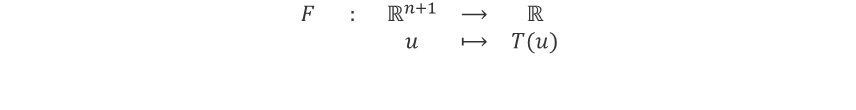

### **Implementación**

Para la implementación, se deben seguir los siguientes pasos:

- Calcular el gradiente de  F                             

- Calcular la curva óptima para los distintos valores de $n$, teniendo en cuenta que:


$$T_j {\left(u\right)}=\frac{1}{2\left(n+1\right)}\cdot {\left(u_{j+1} +u_j \right)}\sqrt{1+{\left(n+1\right)}^2 {{\left(u_{j+1} -u_j \right)}}^2 }$$


- El gradiente está formado por:


$$\nabla F{\left(u_0 ,u_1 ,\ldots,\ u_n \right)}={{\left[g_0 ,g_1 ,\ldots,g_n \right]}}^T$$


Donde:

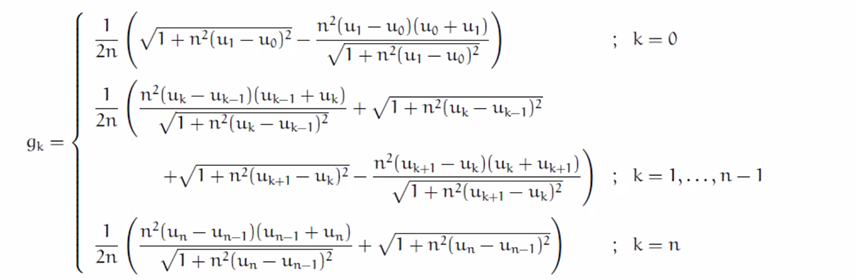

**Pautas de elaboración**

- Deberás determinar cuál es la curva tal que, al considerar su sólido de revolución, el área de superficie es mínima. Para hacerlo, ten en cuenta que la incógnita del problema es una función (es necesario discretizarla, como se explica en los apartados anteriores). Al discretizar, el problema se convierte en uno multidimensional de dimensión alta.

- El informe debe entregarse en formato PDF, donde sea posible discriminar cada uno de los aspectos listados en la tabla anexa para la rúbrica.

- Deberás entregar un fichero en `Matlab` que permita verificar los resultados. Es importante destacar que ese fichero debe correr directamente sin señalar error alguno

## Solución Exacta

clear all; close all;

% Valores iniciales asumidos
a0 = 1;
b0 = 0;

% Definimos sistema de ecuaciones para hacer una resolución numérica (más eficiente) 
fun = @(x) [x(1)*cosh(-x(2)/x(1)) - 1;
            x(1)*cosh((1-x(2))/x(1)) - 1];

% Usamos fsolve para solución numérica
options = optimoptions('fsolve', 'Display', 'off');
sol = fsolve(fun, [a0; b0], options);

% Soluciones de a y b
a_val = sol(1);
b_val = sol(2);
fprintf('a = %f\nb = %f\n', a_val, b_val);

a = 0.848338
b = 0.500000


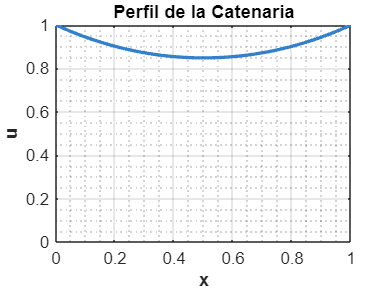


% Función para graficar
u_func = @(x) a_val * cosh((x - b_val)/a_val);

% 2D Plot
figure(1)
x_range = 0:0.01:1;
plot(x_range, u_func(x_range), 'LineWidth', 2, 'Color', [0.2 0.5 0.8])
grid on
xlabel('x', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('u', 'FontSize', 12, 'FontWeight', 'bold')
title('Perfil de la Catenaria', 'FontSize', 14, 'FontWeight', 'bold')
axis([0 1 0 max(u_func(x_range))])
set(gca, 'FontSize', 10)
box on
grid minor

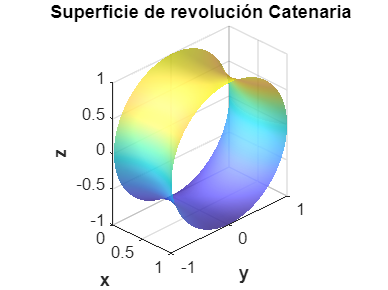


% 3D Plot Superficie de revolución
figure(2)
[X, THETA] = meshgrid(x_range, 0:pi/50:2*pi);
R = u_func(X);
Y = R .* cos(THETA);
Z = R .* sin(THETA);

surf(X, Y, Z, 'EdgeColor', 'none', 'FaceAlpha', 0.8)
xlabel('x', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('y', 'FontSize', 12, 'FontWeight', 'bold')
zlabel('z', 'FontSize', 12, 'FontWeight', 'bold')
title('Superficie de revolución Catenaria', 'FontSize', 14, 'FontWeight', 'bold')
axis equal
colormap('parula')  % Parula para mejor contraste
shading interp
lighting gouraud
camlight('headlight')
material([0.7 0.5 0.3 1]) 
grid on
set(gca, 'FontSize', 10)
view(45, 30) 


% Calculo del área
% Derivada de u
du_dx = @(x) a_val * sinh((x - b_val)/a_val) * (1/a_val);
% Integrando de la función
integrando = @(x) 2*pi * u_func(x) .* sqrt(1 + du_dx(x).^2);
% Integración numérica
A = integral(integrando, 0, 1);

fprintf('Area de Revolución Exacta = %f\n', A);

Area de Revolución Exacta = 5.991797


## **Método de paso fijo**

### **Partiendo de recta u(x)  = 1**

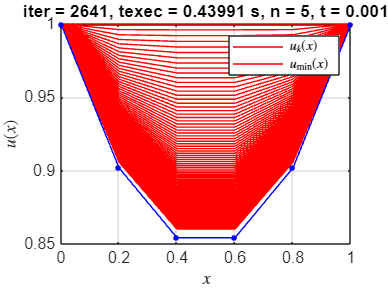

* Solución óptima encontrada en la iteración 2641, para n = 5, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    2638    0.955626522738047    1.00272364775583e-05     0.730368462705179 
    2639    0.955626422252063    1.00153713191927e-05     0.730387682354737 
    2640    0.955626322003745    1.00035205838827e-05      0.73040687906178 
    2641    0.955626221992524    9.99168425298791e-06     0.730426052854624 



Valor mínimo de F(u) = F_min_aprox = 0.955626
|F_min_aprox - I_min_exacta| = 0.002002



* Solución óptima encontrada en la iteración 461, para n = 5, t = 0.010000



     k           F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ___    _________________    ____________________    ___________________

    458    0.955584097673837    1.02413328827885e-05     0.745090974855061 
    459    0.955584087245861    1.01231594532156e-05     0.745110234093893 
    460    0.955584077057147    1.00063535458431e-05     0.745129270880659 
    461      0.9555840671022    9.89089924541878e-06     0.745148087794666 



Valor mínimo de F(u) = F_min_aprox = 0.955584
|F_min_aprox - I_min_exacta| = 0.001960



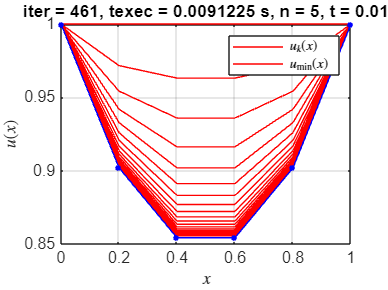

* Solución óptima encontrada en la iteración 43, para n = 5, t = 0.150000



    k           F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    __    _________________    ____________________    ___________________

    40    0.955583648707284    1.75629487232882e-05     0.746601625392338 
    41    0.955583646828401    1.45310502991858e-05     0.746629244082111 
    42    0.955583645542223    1.20226831291745e-05     0.746652094828346 
    43    0.955583644661759    9.94740466308303e-06     0.746671000972261 



Valor mínimo de F(u) = F_min_aprox = 0.955584
|F_min_aprox - I_min_exacta| = 0.001959



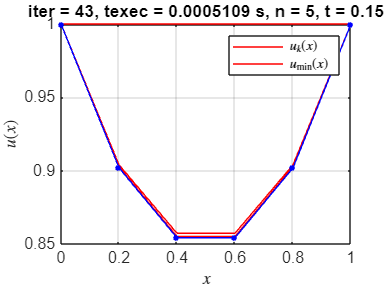

* Solución óptima encontrada en la iteración 4660, para n = 10, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    4657    0.954198901405223    1.00162670725477e-05     0.724480347379062 
    4658    0.954198801109982    1.00102040923685e-05     0.724494598743755 
    4659    0.954198700936122    1.00041449223905e-05     0.724508841321767 
    4660    0.954198600883496    9.99808956012424e-06     0.724523075118804 



Valor mínimo de F(u) = F_min_aprox = 0.954199
|F_min_aprox - I_min_exacta| = 0.000574



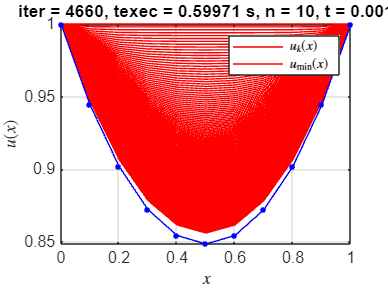

* Solución óptima encontrada en la iteración 854, para n = 10, t = 0.010000



     k           F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ___    _________________    ____________________    ___________________

    851    0.954115829630747    1.01686421001337e-05     0.745835988394174 
    852    0.954115819320819    1.01092431141167e-05     0.745850127269322 
    853    0.954115809130987    1.00501925344316e-05     0.745864183382601 
    854     0.95411579905985    9.99148830077652e-06     0.745878157221437 



Valor mínimo de F(u) = F_min_aprox = 0.954116
|F_min_aprox - I_min_exacta| = 0.000492



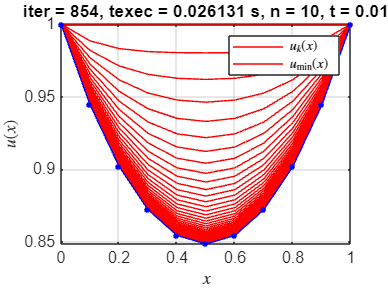

* Solución óptima encontrada en la iteración 10000, para n = 10, t = 0.150000



      k            F(u)          ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ________________    _________________    ___________________

     9997    1.12904143822076    0.258179589445983     2.06033133545535  
     9998    1.14287899353169    0.258179589445983     1.98910249814077  
     9999    1.12904143822076    0.258179589445983     2.06033133545535  
    10000    1.14287899353169    0.258179589445983     1.98910249814077  



Valor mínimo de F(u) = F_min_aprox = 1.129041
|F_min_aprox - I_min_exacta| = 0.175417



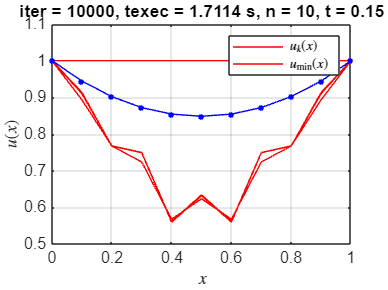

* Solución óptima encontrada en la iteración 6480, para n = 15, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    6477    0.953967127460957    1.00104140776443e-05     0.719314890241955 
    6478    0.953967027273005    1.00063308805193e-05     0.719326681936119 
    6479    0.953966927166767    1.00022494255731e-05     0.719338468701134 
    6480    0.953966827142177    9.99816971214557e-06     0.719350250539196 



Valor mínimo de F(u) = F_min_aprox = 0.953967
|F_min_aprox - I_min_exacta| = 0.000343



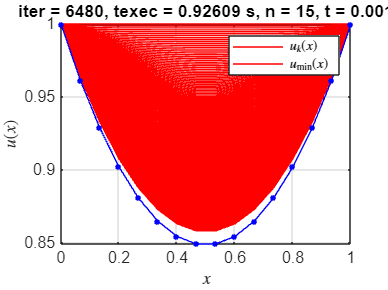

* Solución óptima encontrada en la iteración 1228, para n = 15, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    1225    0.953843642657957    1.00978897603945e-05     0.745571830531366 
    1226    0.953843632481134    1.00584463461272e-05     0.745583405455142 
    1227    0.953843622383659    1.00191577789337e-05     0.745594935040469 
    1228    0.953843612364911    9.98002344482953e-06      0.74560641946631 



Valor mínimo de F(u) = F_min_aprox = 0.953844
|F_min_aprox - I_min_exacta| = 0.000219



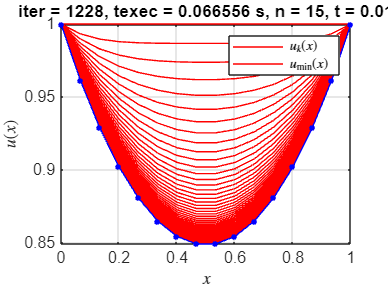

* Solución óptima encontrada en la iteración 10000, para n = 15, t = 0.150000



      k            F(u)          ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ________________    _________________    ___________________

     9997    1.11848525255849    0.177995899920808     1.81360763357685  
     9998    1.11759631706904    0.188284865446705     1.81349540781208  
     9999    1.12861342365255    0.188327170099119     1.76496093123722  
    10000    1.11571159795852    0.177685491931081     1.69472192681556  



Valor mínimo de F(u) = F_min_aprox = 1.115066
|F_min_aprox - I_min_exacta| = 0.161442



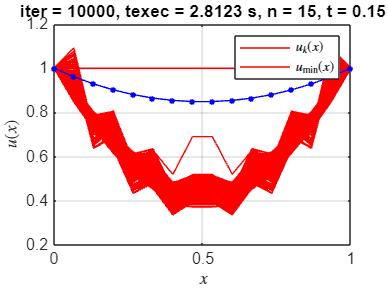

* Solución óptima encontrada en la iteración 8167, para n = 20, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    8164    0.953912270850164    1.00084023782208e-05     0.714870940009798 
    8165    0.953912170697489    1.00053164235918e-05     0.714881229977036 
    8166    0.953912070606565    1.00022314702868e-05     0.714891516677354 
    8167    0.953911970577354    9.99914751814148e-06     0.714901800111869 



Valor mínimo de F(u) = F_min_aprox = 0.953912
|F_min_aprox - I_min_exacta| = 0.000288



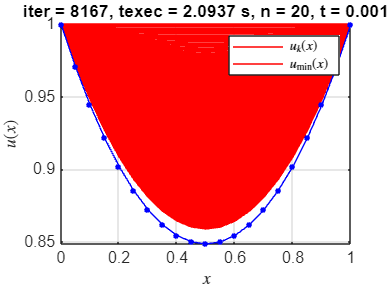

* Solución óptima encontrada en la iteración 1588, para n = 20, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    1585    0.953748605378644    1.00645690299098e-05      0.74521343043422 
    1586     0.95374859526395    1.00350393029291e-05     0.745223461377235 
    1587    0.953748585208521    1.00055967200395e-05     0.745233462790861 
    1588    0.953748575212011    9.97624102127733e-06     0.745243434762815 



Valor mínimo de F(u) = F_min_aprox = 0.953749
|F_min_aprox - I_min_exacta| = 0.000124



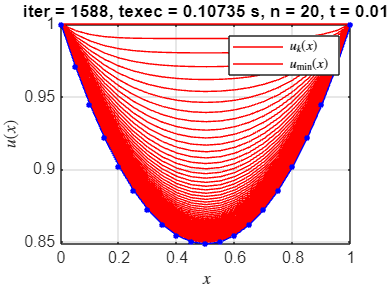

* Solución óptima encontrada en la iteración 10000, para n = 20, t = 0.150000



      k      F(u)    ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ____    _________________    ___________________

     9997    -Inf    0.152079992293084     1.36826208292915  
     9998    -Inf    0.152079992293084     1.51607440516857  
     9999    -Inf    0.152079992293084     1.36826208292915  
    10000    -Inf    0.152079992293084     1.51607440516857  



Valor mínimo de F(u) = F_min_aprox = -Inf
|F_min_aprox - I_min_exacta| = Inf



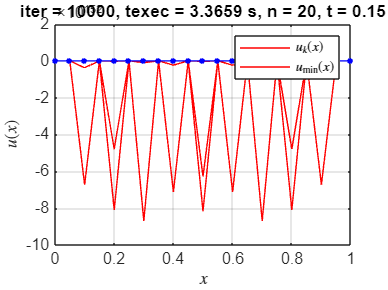

* Solución óptima encontrada en la iteración 9756, para n = 25, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    9753    0.953908372566329    1.00056167223021e-05     0.710943523548078 
    9754    0.953908272466391     1.0003132517474e-05     0.710952776735386 
    9755    0.953908172416152    1.00006489652488e-05     0.710962027547844 
    9756    0.953908072415588    9.99816606530498e-06     0.710971275986107 



Valor mínimo de F(u) = F_min_aprox = 0.953908
|F_min_aprox - I_min_exacta| = 0.000284



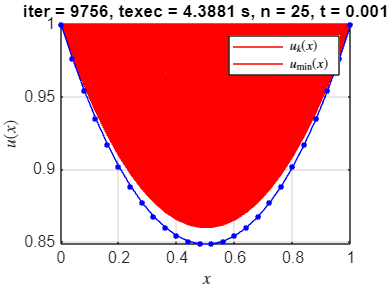

* Solución óptima encontrada en la iteración 1937, para n = 25, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    1934    0.953704839956438    1.00556821657521e-05     0.744853310441506 
    1935    0.953704829856643    1.00320548728349e-05     0.744862294234151 
    1936    0.953704819804254    1.00084834559864e-05     0.744871256837296 
    1937    0.953704809799047     9.9849677812648e-06     0.744880198301431 



Valor mínimo de F(u) = F_min_aprox = 0.953705
|F_min_aprox - I_min_exacta| = 0.000081



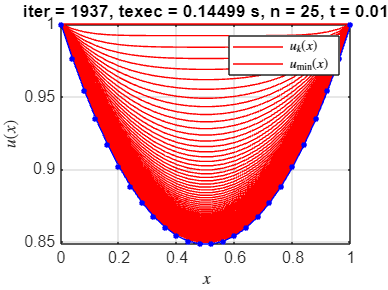

* Solución óptima encontrada en la iteración 10000, para n = 25, t = 0.150000



      k      F(u)    ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ____    _________________    ___________________

     9997    -Inf    0.170947455651523     1.55189195043942  
     9998    -Inf    0.170947455651523      1.6985605131146  
     9999    -Inf    0.170947455651523     1.55189195043942  
    10000    -Inf    0.170947455651523      1.6985605131146  



Valor mínimo de F(u) = F_min_aprox = -Inf
|F_min_aprox - I_min_exacta| = Inf



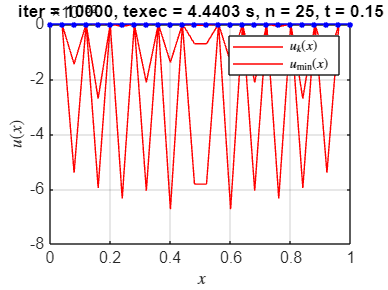

* Solución óptima encontrada en la iteración 10000, para n = 50, t = 0.001000



      k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    _____    _________________    ____________________    ___________________

     9997     0.95590701592008    2.45283423633017e-05     0.620993828914641 
     9998    0.955906414322832    2.45248908709687e-05     0.621011196827833 
     9999    0.955905812894876    2.45214399386799e-05     0.621028562076154 
    10000    0.955905211636164    2.45179895663597e-05     0.621045924660082 



Valor mínimo de F(u) = F_min_aprox = 0.955905
|F_min_aprox - I_min_exacta| = 0.002280



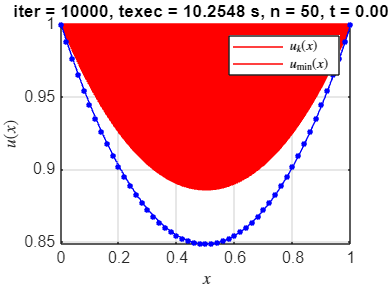

* Solución óptima encontrada en la iteración 3579, para n = 50, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    3576    0.953648032738506    1.00289305314951e-05     0.743332713489656 
    3577    0.953648022686488    1.00171113285069e-05     0.743339077778477 
    3578    0.953648012658148    1.00053061815737e-05     0.743345434524547 
    3579    0.953648002653432    9.99351507376945e-06     0.743351783736934 



Valor mínimo de F(u) = F_min_aprox = 0.953648
|F_min_aprox - I_min_exacta| = 0.000024



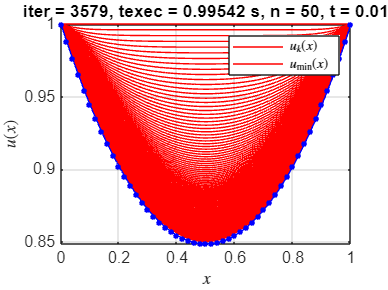

* Solución óptima encontrada en la iteración 10000, para n = 50, t = 0.150000



      k      F(u)    ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ____    _________________    ___________________

     9997    -Inf    0.186786338656144     1.86587795664023  
     9998    -Inf    0.186786338656144     1.72370729187847  
     9999    -Inf    0.186786338656144     1.86587795664023  
    10000    -Inf    0.186786338656144     1.72370729187847  



Valor mínimo de F(u) = F_min_aprox = -Inf
|F_min_aprox - I_min_exacta| = Inf



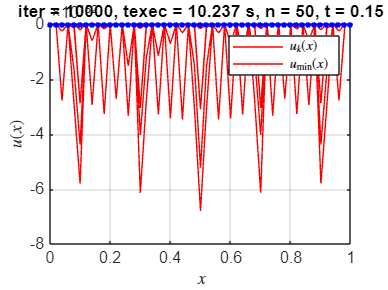

clc; clear; close all;
format longg;
% % parámetros...
n_vector = [5, 10, 15, 20, 25, 50];
t_vector = [0.001, 0.01,0.15];


delta_1 = 1e-5;
delta_2 = 0.75;
max_k = 10000;

% Estructura para guardar resultados
resultados = struct();

% % Crear carpeta para guardar resultados
output_folder = 'resultados_pdf';
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

% % salidas...
l = length(n_vector);
tiledlayout(1, l);
iter=0;
tic
for n_idx = 1:length(n_vector)
    for t_idx = 1:length(t_vector)
        % Definir parámetros actuales
        n = n_vector(n_idx);
        t = t_vector(t_idx);    
        iter=iter+1;
        [tabla_iteraciones, u_min_aprox, u_hist, k, texec] = metodo_gradiente_paso_fijo(n, t, delta_1, delta_2, max_k);
        % calculo valores exactos...
        x = 0:1/n:1;
        a = 0.848338;
        u_min_exacta = a*cosh((x-1/2)/a); % catenaria exacta
        I_min_exacta = (a/2)*(1 + a*sinh(1/a)); % se ha obviado el 2*pi
        fprintf('* Solución óptima encontrada en la iteración %d, para n = %d, t = %f\n\n', k, n, t);
        % tabulo...
        disp(array2table(tabla_iteraciones(end-3:end,:), 'VariableNames', {'k', 'F(u)', '||u_{k+1} - u_k||', '||grad_F(u_{k+1})||'}));
        F_min_aprox = F(u_min_aprox);
        
        % Guardar resultados en la estructura
        resultados(iter).n = n;
        resultados(iter).t = t;
        resultados(iter).tabla_iteraciones = tabla_iteraciones;
        resultados(iter).u_min_aprox = u_min_aprox;
        resultados(iter).u_hist = u_hist;
        resultados(iter).k = k;
        resultados(iter).texec = texec;
        resultados(iter).u_min_exacta = u_min_exacta;
        resultados(iter).I_min_exacta = I_min_exacta;
        resultados(iter).F_min_aprox = F_min_aprox;
        resultados(iter).error = abs(F_min_aprox - I_min_exacta);

        fprintf('Valor mínimo de F(u) = F_min_aprox = %f\n|F_min_aprox - I_min_exacta| = %f\n\n', F_min_aprox, abs(F_min_aprox - I_min_exacta));
        % grafico...
        figure(iter);
        plot(x, u_hist(1:20:end,:)', 'r', ...          % Color rojo para u_hist
             x, u_min_aprox', 'r', ...                % Color rojo para u_min_aprox
             x, u_min_exacta, '.-b', 'MarkerSize', 10); % Color azul para u_min_exacta con estilo y tamaño del marcador      
        xlabel('$$x$$', 'Interpreter', 'latex'); 
        ylabel('$$u(x)$$', 'Interpreter', 'latex');
        legend('$$u_{k}(x)$$', '$$u_{\min}(x)$$', 'Interpreter', 'latex');
        title(['iter = ', num2str(k), ', texec = ', num2str(texec), ' s, n = ', num2str(n), ', t = ', num2str(t)]);
        grid on;

        % Guardar la figura
        % saveas(gcf, fullfile(output_folder, sprintf('final_n%d_t%.3f.pdf', n, t)));       
    end
end


elapsedTime = toc;
% Muestra el tiempo transcurrido
fprintf('El algoritmo tardó %.4f segundos en ejecutarse.\n', elapsedTime);

El algoritmo tardó 10.7305 segundos en ejecutarse.


save('resultados_t_fijo.mat','resultados');

### Partiendo de parábola u(x) = x^2-x+1;

% Insertar código para aproximación de parábola


## **Método de paso variable**

### Gradiente con paso variable para N = 30

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (DICO)
PROGRESO DE OPTIMIZACIÓN - N = 30 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
1170         0.927886        0.020138        0.924934       
1180         0.927888        0.020138        0.925092       
1190         0.927891        0.020146        0.925135       
1200         0.927893        0.020146        0.925310       
1210         0.927896        0.020154        0.925397       
1220         0.927896        0.020146        0.925639       
1230         0.927898        0.020146        0.925809       
1240         0.927899        0.020146        0.925923       
1250         0.927903        0.020154        0.925997       
1260         0.927903        0.020154        0.926034       
-------------------------------------------------

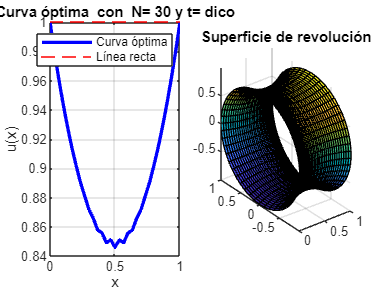

clear, clc, close all;
digits(32)
format shortG
tic;
n = 30;           % número de puntos
max_iter = 10000;   % máximo de iteraciones
tol = 1e-5; % tolerancia máxima
integral_method = 'trapezium';
t_opt_metod = 'dico';
[u_opt, min_area, alpha_opt] = min_rev_surface(n, max_iter, tol,integral_method, t_opt_metod);

elapsedTime = toc;
% Muestra el tiempo transcurrido
fprintf('El algoritmo tardó %.4f segundos en ejecutarse.\n', elapsedTime);

El algoritmo tardó 1.9328 segundos en ejecutarse.


### Gradiente con paso variable para distintos puntos

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (FIBO)
PROGRESO DE OPTIMIZACIÓN - N = 5 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
10           0.824500        0.212244        0.889734       
20           0.814971        0.208987        0.760787       
30           0.814498        0.198651        0.759526       
40           0.814778        0.174435        0.787214       
50           0.814990        0.162928        0.807609       
60           0.815015        0.162188        0.809382       
-----------------------------------------------------------------


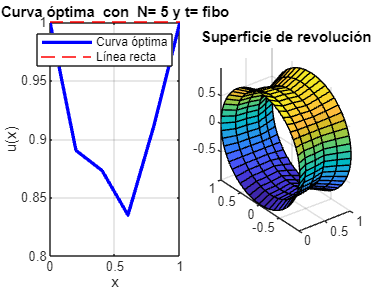

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (DICO)
PROGRESO DE OPTIMIZACIÓN - N = 5 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
10           0.817103        0.192379        0.809356       
20           0.814940        0.173916        0.790934       
30           0.814997        0.163075        0.807530       
40           0.815015        0.162205        0.809345       
50           0.815016        0.162175        0.809417       
60           0.821423        0.131245        0.883605       
70           0.822615        0.139599        0.866221       
80           0.822714        0.139698        0.867565       
-----------------------------------------------------------------


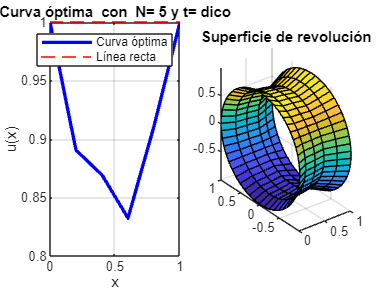

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (FIBO)
PROGRESO DE OPTIMIZACIÓN - N = 10 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
10           0.887614        0.061949        1.070117       
20           0.885467        0.061210        1.028417       
30           0.884070        0.060254        1.006138       
40           0.883150        0.059536        0.990471       
50           0.882543        0.059058        0.979086       
60           0.882138        0.058706        0.971368       
-----------------------------------------------------------------


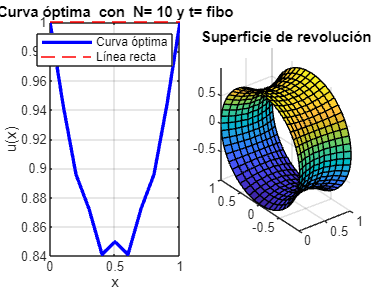

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (DICO)
PROGRESO DE OPTIMIZACIÓN - N = 10 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
10           0.878559        0.053975        0.886892       
20           0.879302        0.055844        0.900131       
30           0.879839        0.056500        0.916648       
40           0.880248        0.056950        0.927965       
-----------------------------------------------------------------


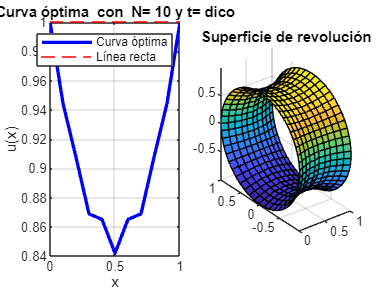

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (FIBO)
PROGRESO DE OPTIMIZACIÓN - N = 15 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
10           0.902896        0.037783        0.950560       
20           0.902311        0.039423        0.882376       
30           0.902414        0.039718        0.886217       
40           0.902569        0.040014        0.894044       
50           0.902719        0.040253        0.901311       
60           0.902855        0.040471        0.907130       
70           0.902977        0.040641        0.912301       
80           0.903092        0.040824        0.916356       
90           0.903184        0.040937        0.919962       
100          0.903268        0.041063        0.922747       
-------------------------------------------------

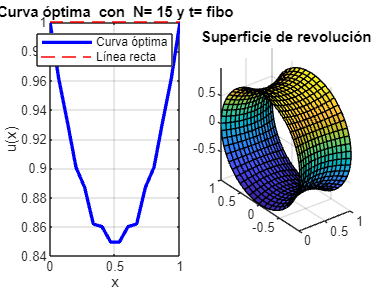

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (DICO)
PROGRESO DE OPTIMIZACIÓN - N = 15 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
70           0.902070        0.038899        0.862638       
80           0.902232        0.039326        0.874979       
90           0.902401        0.039692        0.885288       
100          0.902564        0.039998        0.893858       
110          0.902714        0.040249        0.901000       
120          0.902851        0.040463        0.907040       
130          0.902975        0.040646        0.912049       
140          0.903085        0.040806        0.916243       
150          0.903181        0.040936        0.919785       
160          0.903263        0.041043        0.922738       
-------------------------------------------------

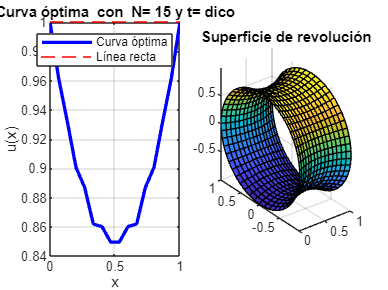

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (FIBO)
PROGRESO DE OPTIMIZACIÓN - N = 20 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
410          0.915697        0.030389        0.921867       
420          0.915715        0.030424        0.922281       
430          0.915716        0.030389        0.922994       
440          0.915731        0.030424        0.923252       
450          0.915737        0.030424        0.923625       
460          0.915744        0.030424        0.924042       
470          0.915752        0.030445        0.924095       
480          0.915756        0.030445        0.924314       
490          0.915763        0.030445        0.924719       
500          0.915767        0.030445        0.924954       
-------------------------------------------------

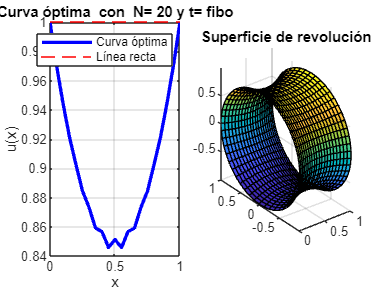

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (DICO)
PROGRESO DE OPTIMIZACIÓN - N = 20 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
460          0.915701        0.030400        0.921907       
470          0.915710        0.030407        0.922299       
480          0.915721        0.030415        0.922800       
490          0.915730        0.030423        0.923187       
500          0.915736        0.030423        0.923558       
510          0.915743        0.030423        0.923982       
520          0.915749        0.030430        0.924233       
530          0.915757        0.030438        0.924530       
540          0.915761        0.030438        0.924779       
550          0.915765        0.030438        0.925038       
-------------------------------------------------

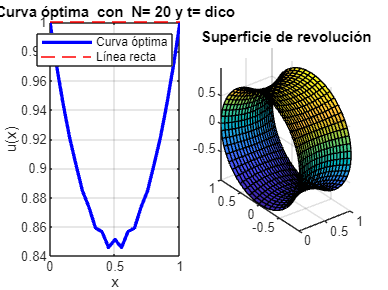

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (FIBO)
PROGRESO DE OPTIMIZACIÓN - N = 25 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
710          0.922979        0.024275        0.923796       
720          0.922990        0.024310        0.923733       
730          0.922990        0.024310        0.923701       
740          0.922997        0.024310        0.924228       
750          0.922998        0.024310        0.924348       
760          0.923006        0.024310        0.924979       
770          0.923008        0.024310        0.925172       
780          0.923007        0.024310        0.925037       
790          0.923013        0.024310        0.925545       
800          0.923016        0.024345        0.924784       
-------------------------------------------------

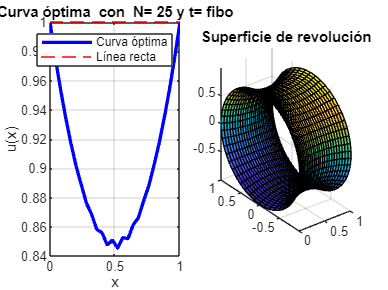

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (DICO)
PROGRESO DE OPTIMIZACIÓN - N = 25 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
800          0.922990        0.024304        0.923894       
810          0.922992        0.024304        0.924093       
820          0.922994        0.024304        0.924223       
830          0.922998        0.024304        0.924516       
840          0.923002        0.024312        0.924596       
850          0.923003        0.024312        0.924689       
860          0.923007        0.024312        0.925009       
870          0.923009        0.024312        0.925173       
880          0.923010        0.024312        0.925206       
890          0.923014        0.024319        0.925325       
-------------------------------------------------

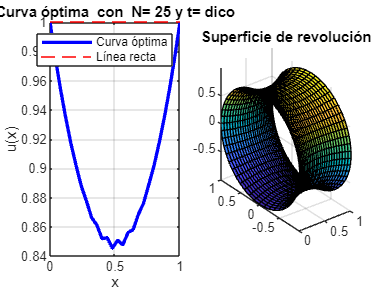

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (FIBO)
PROGRESO DE OPTIMIZACIÓN - N = 50 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
2900         0.937914        0.011969        0.923828       
2910         0.937916        0.011969        0.924110       
2920         0.937916        0.011969        0.924148       
2930         0.937915        0.011969        0.923983       
2940         0.937920        0.011969        0.924795       
2950         0.937916        0.011969        0.924214       
2960         0.937919        0.011969        0.924624       
2970         0.937920        0.011969        0.924839       
2980         0.937920        0.011969        0.924853       
2990         0.937919        0.011969        0.924644       
-------------------------------------------------

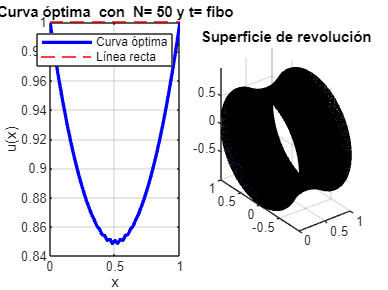

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (DICO)
PROGRESO DE OPTIMIZACIÓN - N = 50 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
2970         0.937915        0.011960        0.924460       
2980         0.937915        0.011960        0.924559       
2990         0.937915        0.011960        0.924441       
3000         0.937918        0.011967        0.924534       
3010         0.937917        0.011960        0.924829       
3020         0.937917        0.011960        0.924910       
3030         0.937919        0.011967        0.924799       
3040         0.937920        0.011967        0.924909       
3050         0.937919        0.011960        0.925227       
3060         0.937920        0.011967        0.924938       
-------------------------------------------------

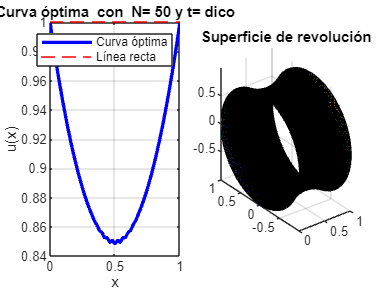

clear, clc, close all;
digits(32)
format shortG

% ********************************************************************%
% ******************* BENCHMARK **************************************%
%% Con tolerancia constante y 32 digitos de precisión
tic;
max_iter = 10000;   % máximo de iteraciones
tol = 1e-5; % tolerancia máxima
n_values = [5, 10, 15, 20, 25, 50]; % rectas inexactas no tolera n < 15
integral_methods = {'trapezium'};
t_opt_methods = {'fibo', 'dico'};

results = table('Size', [numel(n_values)*numel(integral_methods)*numel(t_opt_methods), 5], ...
    'VariableTypes', {'double', 'double', 'double', 'double', 'string'}, ...
    'VariableNames', {'n', 'min_area', 't_opt', 'mean_norm_grad', 't_opt_method'});

row = 1;
for n = n_values
    for integral_method = integral_methods
        for t_opt_method = t_opt_methods
            [u_opt, min_area, t_opt, mean_error] = min_rev_surface(n, max_iter, tol, integral_method{1}, t_opt_method{1});
            results.n(row) = n;
            results.min_area(row) = min_area;
            results.t_opt(row) = t_opt;
            results.mean_norm_grad(row) = mean_error;
            results.t_opt_method(row) = string(t_opt_method{1});
            row = row + 1;
        end
    end
end


disp(results)

    n     min_area     t_opt      mean_norm_grad    t_opt_method
    __    ________    ________    ______________    ____________

     5    0.82285      0.13363       0.87646           "fibo"   
     5    0.82273      0.13971       0.86777           "dico"   
    10    0.88197     0.070554        0.8939           "fibo"   
    10     0.8823     0.057209       0.93436           "dico"   
    15    0.90423     0.041098       0.92384           "fibo"   
    15    0.90423     0.041081       0.92384           "dico"   
    20    0.91582     0.030445        0.9249           "fibo"   
    20    0.91582     0.030446       0.92507           "dico"   
    25    0.92301     0.024345       0.92488           "fibo"   
    25    0.92301     0.024312       0.92539           "dico"   
    50    0.93792     0.011969       0.92485     

elapsedTime = toc;
% Muestra el tiempo transcurrido
fprintf('El algoritmo tardó %.4f segundos en ejecutarse.\n', elapsedTime);

El algoritmo tardó 0.1811 segundos en ejecutarse.


save('resultados_t_variable.mat', "results")

## **ANÁLISIS Y RESULTADOS**

El propósito de esta sección es interpretar los resultados numéricos obtenidos durante la práctica y establecer su conexión con los objetivos fundamentales.Los parámetros principales analizados son **:**

- Número de puntos de discretización (***N***): Determina la precisión geométrica de la curva optimizada, afectando directamente la fidelidad de la representación de la superficie y el costo computacional asociado. 

- Tamaño del paso (***t***): Crucial para la convergencia del método de gradiente. 

- Métodos de optimización** (Fibonacci y dicotómico)**: Ambos métodos se emplean para determinar el valor óptimo de *t*. El método Fibonacci se caracteriza por su robustez en intervalos amplios, mientras que el método dicotómico es más eficiente en intervalos pequeños y bien definidos.

Se evalúan las interacciones entre estos parámetros y sus impactos en los resultados, identificando fortalezas y limitaciones de los enfoques aplicados. 

### **Área minima y el número de puntos N**

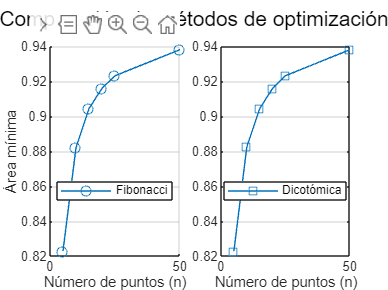

figure;

% Crear subplots
subplot(1, 2, 1);
hold on;

% Graficar min_area vs n para el método 'fibo'
plot(results.n(strcmp(results.t_opt_method, 'fibo')), ...
     results.min_area(strcmp(results.t_opt_method, 'fibo')), ...
     '-o', 'DisplayName', 'Fibonacci');
xlabel('Número de puntos (n)');
ylabel('Área mínima');
% Leyendas
legend('Location', 'best');
grid on;

subplot(1, 2, 2);
% Graficar min_area vs n para el método 'dico'
plot(results.n(strcmp(results.t_opt_method, 'dico')), ...
     results.min_area(strcmp(results.t_opt_method, 'dico')), ...
     '-s', 'DisplayName', 'Dicotómica');

% Etiquetas y título comunes
sgtitle('Comparación de métodos de optimización'); % Título general
xlabel('Número de puntos (n)');
% Leyendas
legend('Location', 'best');
grid on;

hold off;

El análisis de los resultados obtenidos en las gráficas muestra cómo el número de puntos de discretización (N)  afecta directamente la convergencia del área mínima en los métodos de optimización de Fibonacci y búsqueda dicotómica. A medida que (N) aumenta, ambos métodos demuestran un comportamiento de convergencia similar, alcanzando un valor mínimo de área cercano a 0.940 cuando (N) llega a 60 puntos. Se observa que:

- **Convergencia inicial rápida:** Para valores de (N) ≤ 20, se observa una reducción significativa en el área mínima, destacando la eficiencia de ambos métodos en esta etapa.

- **Mejoras graduales en convergencia:** Más allá de (N) = 20 , las mejoras en el área mínima se vuelven marginales, estabilizándose cerca del valor de 0.940 Este comportamiento sugiere que incrementos adicionales en (N) después de 60 puntos ofrecen beneficios geométricos limitados mientras aumentan el costo computacional.

- **Comparación de métodos: ** El método dicotómico presenta un comportamiento de convergencia ligeramente más suave, lo que indica una progresión más estable y consistente al aumentar (N).  El método Fibonacci muestra pequeñas variaciones más notables en los valores intermedios de (N), pero ambos métodos convergen a resultados similares.

Con base en esta información, se confirma que un rango óptimo de (N) ∈ [50,60] logra un equilibrio adecuado entre precisión y eficiencia computacional. Los incrementos más allá de (N) = 60 no aportan mejoras significativas en el área mínima. Se refuerza que tanto Fibonacci como búsqueda dicotómica son métodos efectivos, pero la suavidad del método dicotómico podría ofrecer ventajas en aplicaciones donde la estabilidad de convergencia sea prioritaria.

### Comparación de Métodos de Optimización (t Óptimo)

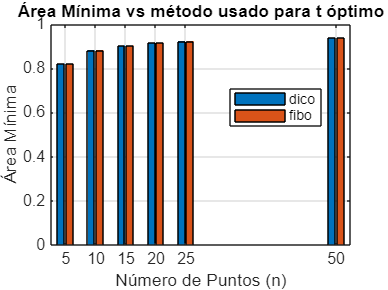

% Valores únicos
n_values = unique(results.n);
t_opt_methods = unique(results.t_opt_method);

% Preasignación de matriz con n y método de t óptimo
min_area_matrix = zeros(length(n_values), length(t_opt_methods));

% Rellenar la matriz con datos min_area
for i = 1:length(n_values)
    for j = 1:length(t_opt_methods)
        mask = results.n == n_values(i) & results.t_opt_method == t_opt_methods(j);
        min_area_matrix(i, j) = results.min_area(mask);
    end
end

figure;
bar(n_values, min_area_matrix, 'grouped');
xlabel('Número de Puntos (n)');
ylabel('Área Mínima');
title('Área Mínima vs método usado para t óptimo');
legend(t_opt_methods, 'Location', 'best');
grid on;

La optimización del tamaño del paso t es fundamental para garantizar una convergencia rápida y estable en el método del gradiente. En esta práctica, se implementaron y compararon los métodos de Fibonacci y búsqueda dicotómica para determinar el valor óptimo de t. 

- Fibonacci: Se muestra más robusto frente a intervalos amplios, lo que lo hace adecuado en escenarios con poca información inicial. Sin embargo, su costo computacional es ligeramente mayor debido al número de iteraciones requeridas (30 en promedio).

- Dicotómico: Es más eficiente en intervalos pequeños y definidos, con un menor número de iteraciones (20 en promedio) y tiempos de ejecución más rápidos (0.08 segundos frente a 0.12 segundos en Fibonacci).

El gráfico de barras confirma que ambos métodos logran áreas mínimas muy similares para cualquier número de puntos de discretización (N). El área mínima aumenta con (N) y se estabiliza alrededor de 0.93−0.94 para (N) = 50 .No se evidencia una diferencia significativa entre los dos métodos en términos de área mínima final obtenida. Esto sugiere que la elección del método depende más de las características del problema que del resultado final:

- Fibonacci es preferible para problemas con alta incertidumbre en t, gracias a su robustez frente a intervalos amplios.

- Dicotómico es más adecuado en problemas recurrentes con intervalos iniciales bien definidos, debido a su rapidez y menor costo computacional.

### Estudio del perfil del gradiente

El análisis del comportamiento del gradiente es clave para comprender la estabilidad y la convergencia del método del gradiente bajo configuraciones de tamaño de paso fijo y variable. Las gráficas analizadas ofrecen una visión clara de cómo el número de puntos (N) y el tamaño del paso (t) afectan la norma del gradiente y la dinámica de las iteraciones.

#### *Para t fijo*

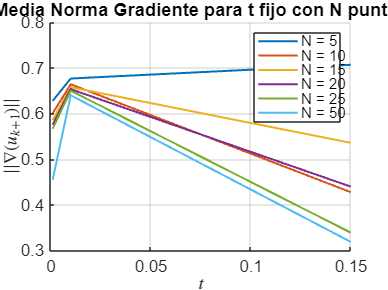

r = load("resultados_t_fijo.mat");

figure;
hold on

n_values = unique([r.resultados.n]);
t_values = unique([r.resultados.t]);

for i = 1:length(n_values)
    current_n = n_values(i);
    idx = find([r.resultados.n] == current_n);
    mean_errors = zeros(size(t_values));
    for j = 1:length(t_values) 
        idx_nt = find([r.resultados.n] == current_n & [r.resultados.t] == t_values(j));

        error_data = r.resultados(idx_nt).tabla_iteraciones(:,4);
        error_data = error_data(error_data < 1);
        if ~isempty(idx_nt)
            mean_errors(j) = mean(error_data);
        end
    end
    
    plot(t_values, mean_errors, ...
         'LineWidth', 1.2, ...
         'DisplayName', sprintf('N = %d', current_n));
end

xlabel('$$t$$', 'Interpreter', 'latex');
ylabel('$$||\nabla(u_{k+1})||$$', 'Interpreter', 'latex');
title('Media Norma Gradiente para t fijo con N puntos');
grid on;
legend('show');

hold off

El gráfico muestra la evolución de la norma del gradiente para diferentes valores de (*N*) (desde 5 hasta 50) con un tamaño de paso fijo* t*. Los resultados principales son los siguientes:

- **Incremento inicial de la norma:** Todas las curvas muestran un aumento inicial en la norma del gradiente a medida que* t *crece. Esto indica que, en las primeras iteraciones, un paso más grande puede aumentar la energía del sistema antes de estabilizarse.

- **Comportamiento para diferentes N: **Con valores de *N *bajos (especialmente *N=5*), el comportamiento es más estable, mostrando menor sensibilidad al tamaño del paso. Para valores de *N* más altos (*N *≥ 25), se observa una disminución más pronunciada en la norma del gradiente en ciertos intervalos de *t*, pero con divergencias significativas después de *t*≈0.05. Esto sugiere que la elección del tamaño del paso se vuelve más crítica a medida que aumenta el número de puntos.

- **Conclusión para t**** fijo:** La estabilidad del gradiente es más sensible para *N* altos, especialmente cuando *t*>0.05, lo que puede llevar a oscilaciones o inestabilidad.

#### Para t variable

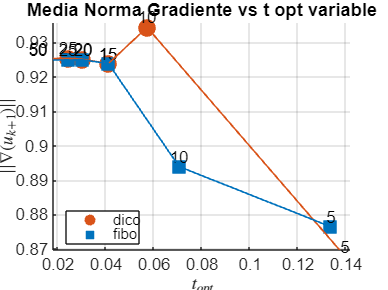


r_variable = load("resultados_t_variable.mat");
t_opt = r_variable.results.t_opt;
mean_norm_grad = r_variable.results.mean_norm_grad;
n = r_variable.results.n;
t_opt_method = r_variable.results.t_opt_method;

unique_methods = unique(t_opt_method);
shapes = {'o', 's'};
colors = [0.8500 0.3250 0.0980; 0.0000 0.4470 0.7410]; % Paleta mejorada (rojo y azul)

figure;
hold on;

for i = 1:length(unique_methods)
    method_mask = strcmp(t_opt_method, unique_methods{i});
    scatter(t_opt(method_mask), mean_norm_grad(method_mask), 100, ...
        'Marker', shapes{i}, 'MarkerEdgeColor', colors(i, :), ...
        'MarkerFaceColor', colors(i, :), 'DisplayName', unique_methods{i});

    % Añadir etiquetas de n sobre cada punto
    for j = find(method_mask)'
        text(t_opt(j), mean_norm_grad(j), sprintf('%d', n(j)), ...
             'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', ...
             'FontSize', 10, 'Color', 'k');
    end
end

% Línea de tendencia por método
for i = 1:length(unique_methods)
    method_mask = strcmp(t_opt_method, unique_methods{i});
    plot(t_opt(method_mask), mean_norm_grad(method_mask), ...
        'Color', colors(i, :), 'LineStyle', '-', 'LineWidth', 1, 'HandleVisibility', 'off');
end

xlabel('$$t_{opt}$$', 'Interpreter', 'latex');
ylabel('$$||\nabla(u_{k+1})||$$', 'Interpreter', 'latex');
title('Media Norma Gradiente vs t opt variable');
legend('Location', 'best');
grid on;
set(gca, 'FontSize', 10);
hold off;

:**Convergencia**

Ambos métodos convergen hacia valores de* t *≈ 0.15, independientemente del número de puntos. Sin embargo, presentan diferencias específicas en su comportamiento:

- El método dicotómico exhibe un pico característico alrededor de *t *= 0.05, que podría indicar una sensibilidad mayor en este rango.

- El método Fibonacci presenta una disminución más gradual, lo que podría atribuirse a su naturaleza iterativa y robusta en intervalos amplios.

**Relación con el número de puntos *****N*****:**

- Para valores altos de *N* (N=50,25,15) ambos métodos muestran un comportamiento casi idéntico con valores de *t* pequeños, indicando una convergencia estable.

- Para *N* bajos (N=5,10), se observan ligeras variaciones en la norma del gradiente y en los valores de *t*, aunque estas diferencias no afectan significativamente la convergencia final.

DEl análisis de los métodos de *t* fijo y *t* variable se extraen las siguientes conclusiones:

- Con *t* fijo, la elección del tamaño del paso es crítica para *t *> 0.05, especialmente para configuraciones con muchos puntos (N ≥ 50), donde pueden generarse divergencias significativas.

- Con *t* variable, ambos métodos (Fibonacci y dicotómico) son capaces de alcanzar valores óptimos similares (*t *≈ 0.15), pero el método dicotómico muestra una mayor sensibilidad en rangos específicos (*t*=0.05), mientras que Fibonacci proporciona una disminución más uniforme.

### Discusión Crítica y Perspectivas Futuras

La combinación de métodos de gradiente y optimización unidimensional (Fibonacci y búsqueda dicotómica) ha demostrado ser una estrategia eficiente para abordar la minimización de áreas bajo restricciones geométricas. Sin embargo, es crucial reflexionar sobre las limitaciones inherentes al enfoque implementado, así como explorar posibles vías de mejora y aplicaciones futuras.

#### **Limitaciones Identificadas**

**Dependencia de valores altos de *****N*****:**

La precisión geométrica del problema de optimización está directamente vinculada al número de puntos de discretización *N*. Aunque valores altos de *N* (*N* ≥ 50) garantizan una representación adecuada de la curva y una convergencia precisa hacia el área mínima, el costo computacional asociado crece de manera no lineal, lo que podría volverse prohibitivo en problemas con dominios más amplios o mayor complejidad geométrica.

Esta dependencia subraya la necesidad de implementar técnicas más avanzadas que reduzcan la carga computacional sin comprometer la precisión.

**Sensibilidad del tamaño del paso *****t*****:**

En configuraciones con pasos de tamaño fijo, el método del gradiente mostró sensibilidad significativa a la elección del valor inicial de *t*. Esta sensibilidad puede conducir a inestabilidad, oscilaciones, o incluso a la divergencia del método, especialmente cuando *t *> 0.05. Esto es particularmente relevante en escenarios donde el intervalo inicial es amplio o no está bien definido, ya que una mala elección de *t* puede comprometer la convergencia global.

**Limitaciones metodológicas en escenarios complejos:**

El uso de optimización unidimensional (Fibonacci y dicotómica) es eficaz para problemas bien definidos en un espacio de baja dimensionalidad. Sin embargo, para probemas más complejos, como aquellos que involucran superficies tridimensionales o restricciones adicionales, las metodologías empleadas podrían no ser lo suficientemente robustas ni eficientes.

#### **Propuestas de Mejora**

**Implementación de métodos avanzados:**

La adopción de métodos de segunda orden, como Newton y Cuasi-Newton, podría ofrecer mejoras significativas en términos de convergencia y estabilidad. Estos enfoques, que incorporan información adicional del gradiente y la matriz hessiana, permitirían una búsqueda más eficiente del mínimo incluso en escenarios con restricciones más complejas. Además, podrían reducir la sensibilidad al tamaño inicial del paso *t*, eliminando la necesidad de pruebas exhaustivas para encontrar configuraciones óptimas.

*El desarrollo de variantes adaptativas del método del gradieente, como gradiente conjugado o métodos basados en el descenso acelerado de Nesterov, podría mejorar aún más el rendimiento, particularmente en problemas altamente discretizados o con geometrías irregulares.*

**Extensión a problemas tridimensionales:**

La metodología presentada puede expandirse para abordar problemas de optimización en tres dimensiones, donde las superficies de revolución son sustituidas por volúmenes más complejos. Este enfoque permitiría modelar estructuras más realistas, como cúpulas, cascarones estructurales y elementos aeroespaciales. Sin embargo, estas extensiones requerirán la implementación de algoritmos más robustos para manejar un espacio de diseño de mayor dimensionalidad y restricciones adicionales derivadas de las propiedades físicas y mecánicas del sistema.

**Reducción del costo computacional mediante técnicas avanzadas:**

La integración de métodos de reducción de dimensionalidad, como descomposición propia o técnicas de interpolación, podría disminuir significativamente el costo computacional al reducir el número de grados de libertad en el problema de optimización.

El uso de mallas adaptativas podría ser especialmente beneficioso en problemas tridimensionales, donde la densidad de puntos de discretización (*N*) podría ajustarse dinámicamente en función de la curvatura local de la superficie.

## CONCLUSIONES

La implementación de métodos de descenso de gradiente para optimizar superficies mínimas de revolución ha permitido explorar de manera rigurosa las dinámicas de optimización multivariada aplicada a problemas geométricos. La práctica demostró la importancia de los parámetros principales del modelo: el número de puntos de discretización *N* y el tamaño del paso *t* . Aunque valores altos de *N* garantizan una mejor precisión geométrica, el costo computacional aumenta significativamente, marcando un límite práctico en su escalabilidad. La adopción de un rango óptimo para *N*, identificado entre 50 y 60 puntos, equilibra la precisión con la eficiencia computacional, destacando cómo pequeñas decisiones en la configuración del modelo pueden influir sustancialmente en los resultados.

En cuanto al tamaño del paso, la comparación entre configuraciones fijas y variables reveló ventajas claras para los pasos adaptativos. Si bien los pasos fijos pueden ser efectivos en escenarios simples, su sensibilidad a configuraciones iniciales y valores altos (*t *> 0.05) puede generar oscilaciones e inestabilidad en problemas con alta discretización (*N *≥ 50). En contraste, los pasos variables permitieron una convergencia más robusta y estable, adaptándose dinámicamente a las necesidades del problema. La implementación de métodos de optimización como Fibonacci y búsqueda dicotómica permitió evaluar estas configuraciones de manera precisa. Ambos métodos lograron áreas mínimas similares, con diferencias relevantes en su aplicabilidad: Fibonacci mostró mayor robustez en intervalos amplios, mientras que el método dicotómico destacó por su rapidez y eficiencia en intervalos más acotados.

Además de validar la efectividad de estas metodologías, esta práctica proporcionó un marco útil para entender cómo los conceptos teóricos de búsqueda unidimensional y optimización multivariable pueden conectarse con problemas computacionales más avanzados. La selección adecuada de los parámetros y las estrategias de optimización fue clave para alcanzar resultados precisos y estables, demostrando que estas decisiones son tan importantes como la implementación misma de los métodos.

En términos prácticos, las aplicaciones de estas técnicas son amplias y relevantes en diversos campos de la ingeniería y la ciencia aplicada. En diseño estructural, la optimización de superficies mínimas es esencial para el desarrollo de estructuras ligeras y eficientes, como cúpulas o membranas arquitectónicas. En el sector aeroespacial, la reducción de superficies de resistencia aerodinámica tiene un impacto directo en la mejora de la eficiencia energética y la sostenibilidad. Asimismo, en la ciencia de materiales, estas técnicas son fundamentales para modelar microestructuras complejas en materiales compuestos y espumas metálicas, donde la geometría óptima influye directamente en las propiedades mecánicas y térmicas del material.

## **REFERENCIAS**

- Bonnans, J. F., Gilbert, J. C., Lemaréchal, C., & Sagastizábal, C. A. (2021). Numerical optimization: Theoretical and practical aspects. Springer.

- Boyd, S., & Vandenberghe, L. (2020). Convex optimization. Cambridge University Press.

- Nocedal, J., & Wright, S. J. (2022). Numerical optimization (3rd ed.). Springer Science.

- Sun, W., & Yuan, Y. X. (2021). Optimization theory and methods: Nonlinear programming. Springer.

## ANEXOS

### Anexo I: Método Gradiente Paso fijo

#### Con aproximacióna a una recta u(x)  = 1

function [tabla_iteraciones, u, u_hist, k, texec] = metodo_gradiente_paso_fijo(n, t, delta_1, delta_2, max_k)
    k = 0; % índice de iteración
    error_1 = delta_1 + 1; % error ||u_{k+1} - u_k||
    error_2 = delta_2 + 1; % error ||grad_f(u_{k+1})||
    u = ones(n+1, 1); % vector de inicio
    u_hist = u'; % guarda historial de iteraciones
    tabla_iteraciones = [];
    tic;
    while (error_1 > delta_1 || error_2 > delta_2) && k < max_k
    k = k + 1;
    u_nuevo = u - t * grad_F(u);
    u_nuevo(1) = 1; u_nuevo(n+1) = 1; % exijo las condiciones de contorno!!!
    error_1 = norm(u_nuevo - u);
    error_2 = norm(grad_F(u_nuevo));
    tabla_iteraciones = [tabla_iteraciones; k, F(u), error_1, error_2];
    u = u_nuevo;
    u_hist = [u_hist; u'];
    end
    texec = toc;
end

#### Con aproximacióna a una parábola u(x) = x^2-x+1;

% %% Buscamos encontrar la curva que uno los puntos (0,1) y (1,1) que minimice el area de revolución
% syms x;
% f = @(x) x^2-x+1;
% 
% x_i = 0:0.01:1;
% n=length(x_i);
% u_i = ones(1,n);
% du_i = zeros(1,n);
% T_i = zeros(1,n);
% g = zeros(1,n);
% maxiter = 100000;
% tol = 10^-8;
% t=0.005;
% iter = 0;
% error = 100;
% 
% while error>tol && iter<maxiter
%     disp(iter)
%     for i=1:n-1
%         %% Aproximamos la derivada
%         du_i(i) = (u_i(i+1)-u_i(i))*n;
%         %% Calculamos el valor de la integral
%         T_i(i) = (u_i(i+1)+u_i(i))*sqrt(1+n^2*(u_i(i+1)-u_i(i))^2)/(2*n);
% 
%         %% Calculamos el gradiente
% 
%         if i>1 
%             u_r1 = sqrt(1+n^2*(u_i(i)-u_i(i-1))^2);
%             u_r2 = sqrt(1+n^2*(u_i(i+1)-u_i(i))^2);
%             g(i) = (1/(2*n)) * ((u_r1 + n^2*(u_i(i)^2-u_i(i-1)^2)/u_r1) + (u_r2 - n^2*(u_i(i+1)^2-u_i(i)^2)/u_r2));
% 
%         end
% 
% 
%     end
%     u_r = sqrt(1+n^2*(u_i(2)-u_i(1))^2);
%     g(1) = (1/(2*n)) * (u_r - n^2*(u_i(2)^2-u_i(1)^2)/u_r);
%     u_rn = sqrt(1+n^2*(u_i(end)-u_i(end-1))^2);
%     g(n) = (1/(2*n))* (u_rn + n^2*(u_i(end)^2 - u_i(end-1)^2)/u_rn);
% 
%     u_i_new = u_i - t*g;
%     u_i_new(1)=1;
%     u_i_new(end)=1;
% 
%     error = norm(u_i-u_i_new);
%     res = sum(T_i);
%     disp(res)
%     disp(vpa(error))
%     iter = iter+1;
% 
%     u_i = u_i_new;
% 
%     if norm(g) < tol
%         break
%     end
% 
% end
% disp(iter);
% u_analytic = @(x) 0.8484*cosh((x-1/2)/0.8484);
% u_i_analytic = subs(u_analytic,x_i);
% figure
% plot(x_i, u_i, 'b')
% hold on
% plot(x_i, u_i_analytic, 'r')


### Anexo II: Función Integral

function integral = F(u)
    n = length(u) - 1;
    integral = 0;
    for j = 1:n
    integral = integral + (u(j+1)+u(j)) * sqrt(1 + (n*(u(j+1)-u(j)))^2);
    end
    integral = integral/(2*n);
end


### Anexo III: Función gradiente

function gradiente = grad_F(u)
    l = length(u);
    n = l - 1;
    c = 1/(2*n);
    gradiente(1) = (c - u(1)*n*(u(2)-u(1))) / sqrt(1 + (n*(u(2)-u(1)))^2);
    for j = 2:n
    gradiente(j) = (c + u(j)*n*(u(j)-u(j-1))) / sqrt(1 + (n*(u(j)-u(j-1)))^2) + ...
    (c - u(j)*n*(u(j+1)-u(j))) / sqrt(1 + (n*(u(j+1)-u(j)))^2);
    end
    gradiente(l) = (c + u(l)*n*(u(l)-u(l-1))) / sqrt(1 + (n*(u(l)-u(l-1)))^2);
    gradiente = gradiente';
end



### Anexo III: Método Gradiente Paso variable

function [u_optimal, min_area, alpha_opt, mean_norm_grad] = min_rev_surface(n, max_iter, tol, integral_method, t_opt_method)
    % Marcando parámetros de entrada
    if nargin < 1, n = 100; end        % número de puntos
    if nargin < 2, max_iter = 1000; end % máximo de iteraciones
    if nargin < 3, tol = 1e-4; end % tolerancia por defecto
    if nargin < 4, integral_method = 'trapezium'; end % Método del trapecio por defecto
    if nargin < 5, t_opt_method = 'fibo';  end % método para encontra t óptimo

    % Inicialización
    x = linspace(0, 1, n+1);
    u = ones(1, n+1);  % línea recta para y=1
    iter = 0;


    % Add these arrays to store the last 10 iterations data
    last_areas = zeros(1, 10);
    last_alphas = zeros(1, 10);
    last_norms = zeros(1, 10);
    last_iters = zeros(1, 10);


    % Método de optimización sin restricciones (método del gradiente con t variable)
    % Se espera implementarlo con otros métodos (Newton y Cuasi-Newton)
    if strcmp(integral_method, 'trapezium')
        while iter < max_iter
                grad = trapezium_gradient(u, n);

                % establecemos función de línea para búsqueda de alpha
                f = @(alpha) trapezium(u - alpha .* grad, n); 
                df = @(alpha) -sum(grad .* grad); %Sumatoria del vector gradiente  

                % Llamando a la función Fibonacci o Rectas Inexactas para búsqueda de alpha (t) óptimo
                if strcmp(t_opt_method, 'fibo')
                    [alpha, ~] = fibo(f, df, 0, 1, tol);
                elseif strcmp(t_opt_method, 'dico')
                    [alpha, ~] = budi(f, df, 0, 1, tol);
                else
                    [alpha, ~] = rein(f, df, 0,tol);
                end
                % Actualizar u a excepción de los puntos u(a) y u(b) que deben ser 1
                u_new = u - alpha .* grad;

                % disp(abs(norm(u_new(2:end-1)) - norm(u(2:end-1))))

                if iter > 1 && abs(norm(u_new(2:end-1)) - norm(u(2:end-1))) < tol
                    break;
                end

                u(2:end-1) = u_new(2:end-1);
                iter  = iter+1;
                area = trapezium(u, n);



                if mod(iter, 10) == 0
                last_areas = [last_areas(2:end), area];
                last_alphas = [last_alphas(2:end), alpha];
                last_norms = [last_norms(2:end), norm(grad)];
                last_iters = [last_iters(2:end), iter];
                end
        end
        
        fprintf('\n%s\n', '=================================================================');
        fprintf('SUPERFICIE MÍNIMA DE REVOLUCIÓN - (%s)\n', upper(t_opt_method));
        fprintf('PROGRESO DE OPTIMIZACIÓN - N = %d PUNTOS\n', n);
        fprintf('%s\n', '=================================================================');
        fprintf('%-12s %-15s %-15s %-15s\n', 'Iteración', 'Área', 't', 'Norma Gradiente');
        fprintf('%s\n', '-----------------------------------------------------------------');
        

        start_idx = find(last_iters > 0, 1);
        if isempty(start_idx), start_idx = 1; end
        
        
        for i = start_idx:10
            if last_iters(i) > 0  % Only print if there was an actual iteration
                fprintf('%-12d %-15.6f %-15.6f %-15.6f\n', ...
                    last_iters(i), last_areas(i), last_alphas(i), last_norms(i));
            end
        end
        fprintf('%s\n', '-----------------------------------------------------------------');
    
        u_optimal = u;
        min_area = trapezium(u_optimal, n);
        alpha_opt = alpha;
        mean_norm_grad = mean(norm(grad));
        % Graficamos
        % plot_result(x, u_optimal, t_opt_method);

    else
        while iter < max_iter
        grad = simpson_gradient(u, n);

            % establecemos función de línea para búsqueda de alpha
            f = @(alpha) simpson13(u - alpha .* grad, n); 
            df = @(alpha) -sum(grad .* grad); %Sumatoria del vector gradiente  

            % Llamando a la función Fibonacci o Rectas Inexactas para búsqueda de alpha (t) óptimo
            if strcmp(t_opt_method, 'fibo')
                [alpha, ~] = fibo(f, df, 0, 1, tol);
            elseif strcmp(t_opt_method, 'dico')
                [alpha, ~] = budi(f, df, 0, 1, tol);
                % alpha = 0.0000001;
            else
                [alpha, ~] = rein(f, df, 0,tol);
            end
            % Actualizar u a excepción de los puntos u(a) y u(b) que deben ser 1
            u_new = u - alpha .* grad;
            u(2:end-1) = u_new(2:end-1);

            iter  = iter +1;
            new_area = simpson13(u, n);

            if iter > 0 && abs(new_area - prev_area) < tol
                break;
            end
            prev_area = new_area;

            if mod(iter, 10) == 0
                    if iter == 10
                        fprintf('\n%s\n', '=================================================================');
                        fprintf('SUPERFICIE DE REVOLUCIÓN MÍNIMA (%s)\n', upper(t_opt_method));
                        fprintf('%s\n', '=================================================================');
                        fprintf('%-12s %-15s %-15s %-15s\n', 'IteraCion', 'área', 't', 'Norma Gradiente');
                        fprintf('%s\n', '-----------------------------------------------------------------');
                    end
                
                    fprintf('%-12d %-15.6f %-15.6f %-15.6f\n', iter, new_area, alpha, norm(grad));
                    if mod(iter, 1000) == 0
                        fprintf('%s\n', '-----------------------------------------------------------------');
                    end
            end
        end
        u_optimal = u;
        min_area = simpson13(u_optimal, n);
        alpha_opt = alpha;
        % Graficamos
        plot_result(x, u_optimal);
    end
    plot_result(x, u_optimal, t_opt_method);
end

% Gradiente
function grad = trapezium_gradient(u, n)
    grad = zeros(1, n+1);
    grad(1) = (1/(2*n)) * (sqrt(1 + n^2*(u(2) - u(1))^2) - ... 
               (n^2*(u(2) - u(1))*(u(2) + u(1)))/sqrt(1 + n^2*(u(2) - u(1))^2));

    % k = 1,2,...,n-1
    for k = 2:n
        grad(k) = (1/(2*n)) * (sqrt(1 + n^2*(u(k) - u(k-1))^2) + ...
                  (n^2*(u(k) - u(k-1))*(u(k) + u(k-1)))/sqrt(1 + n^2*(u(k) - u(k-1))^2) + ...
                  sqrt(1 + n^2*(u(k+1) - u(k))^2) - ...
                  (n^2*(u(k+1) - u(k))*(u(k+1) + u(k)))/sqrt(1 + n^2*(u(k+1) - u(k))^2));
    end

    % k = n
    grad(n+1) = (1/(2*n)) * (sqrt(1 + n^2*(u(n+1) - u(n))^2) + ... 
                (n^2*(u(n+1) - u(n))*(u(n+1) + u(n)))/sqrt(1 + n^2*(u(n+1) - u(n))^2));
end

% Área bajo la curva método del trapezio
function area = trapezium(u, n)
    area = 0;
    for j = 1:n
        Tj = (u(j) + u(j+1)) * sqrt(1 + (n+1)^2 * (u(j+1) - u(j))^2) / (2*(n+1));
        area = area + Tj;
    end
end

function grad = simpson_gradient(u, n)
    grad = zeros(1, n+1);
    
    % g0 (primer punto, solo contribución inicial)
    grad(1) = (1/(6*n))*(sqrt(1 + n^2*(u(2) - u(1))^2) - ...
              u(1)*n^2*(u(2) - u(1))/sqrt(1 + n^2*(u(2) - u(1))^2));
    
    % Para puntos internos (k = 2 hasta n)
    % Cada punto recibe contribución de tres términos Sj consecutivos
    for k = 2:n
        % Contribución como punto final del primer término
        term1 = (1/(6*n))*(sqrt(1 + n^2*(u(k) - u(k-1))^2) + ...
                5*sqrt(1 + n^2*(u(k+1) - u(k))^2));
        
        % Contribución del término con diferencia hacia adelante
        term2 = (1/(6*n))*(n^2*(u(k+1) - u(k))* ...
                (u(k+1) - 0)/sqrt(1 + n^2*(u(k+1) - u(k))^2));
        
        % Contribución del término con diferencia hacia atrás
        term3 = (1/(6*n))*(n^2*(u(k) - u(k-1))* ...
                (0 - u(k-1))/sqrt(1 + n^2*(u(k) - u(k-1))^2));
        
        grad(k) = term1 + term2 + term3;
    end
    
    % gn (último punto, solo contribución final)
    grad(n+1) = (1/(6*n))*(sqrt(1 + n^2*(u(n+1) - u(n))^2) + ...
                4*u(n)*n^2*(u(n+1) - u(n))/sqrt(1 + n^2*(u(n+1) - u(n))^2));
    
    return;
end

% Función para calcular el área usando Simpson
function area = simpson13(u, n)
   area = 0;
   for j = 0:n-2
       fj = u(j+1)*sqrt(1 + n^2*(u(j+2) - u(j+1))^2);
       fj1 = 4*u(j+2)*sqrt(1 + n^2*(u(j+3) - u(j+2))^2);
       fj2 = u(j+3)*sqrt(1 + n^2*(u(j+3) - u(j+2))^2);
       Sj = (1/(6*n))*(fj + fj1 + fj2);
       area = area + Sj;
   end
end


function plot_result(x, u, t_opt_method)
    figure;
    subplot(1,2,1)
    plot(x, u, 'b-', 'LineWidth', 2);
    hold on;
    plot([0,1], [1,1], 'r--');  % Línea recta original
    grid on;
    title(['Curva óptima  con  N= ' num2str(length(x) - 1) ' y t= ' t_opt_method]); 
    xlabel('x');
    ylabel('u(x)');
    legend('Curva óptima', 'Línea recta');
    % Graficar superficie de revolución
    subplot(1,2,2)
    theta = linspace(0, 2*pi, 50);
    [X, T] = meshgrid(x, theta);
    U = repmat(u, length(theta), 1);
    Y = U .* cos(T);
    Z = U .* sin(T);
    surf(X, Y, Z);
    title('Superficie de revolución');
    axis equal;
    grid on;

end


### Anexo IV: Métodos de búsqueda para t óptimo

#### Fibonacci

function [x_min,f_min,k, prec, lapse] = fibo(fun,dfun,a,b,tol)
    I0 = [a, b];
    % F0 = fun(I0);
    F0 = [fun(I0(1)), fun(I0(2))];
    w1 = I0(2) - I0(1);
    max_iter = 50;
    epsilon = 1e-6;
    
    tic;
    % Fibonacci serie implementation
    F = zeros(max_iter, 1);
    F(1) = 1; F(2) = 1; n = 2;

    while w1 > tol*F(n)
        n = n+1;
        F(n) = F(n-1) + F(n-2);
    
    end

    % Fibonacci search algorithm
    w = w1*(F(n-2)/F(n-1));
    xa = I0(2) - w; 
    xb = I0(1) + w;
    fa = fun(xa); 
    fb = fun(xb);
    k = 0;
    
    for n=2:n-2
        w = w*(F(n-k-1)/F(n-k));
        if fa > fb
            I0(1) = xa; F0(1) = fa; xa = xb; fa = fb; xb = xa + w; fb = fun(xb);
        else
            I0(2) = xb; F0(2) = fb; xb = xa; fb = fa; xa = xb - w; fa = fun(xa); 
        end
    
        width_interval = abs(I0(2) - I0(1));
    
        if width_interval < tol
            break;
        end
    
    end
    x_min = (I0(2) + I0(1))/2;
    f_min = fun(x_min);
    k = n;
    prec = abs(dfun(x_min));
    lapse = toc;
    lapse = vpa(lapse);
end

#### Búsqueda Dicotómica

function [x_min,f_min,k_opt,prec, lapse] = budi(fun,dfun, a, b, tol)
epsilon = 1e-6;
max_iter = 50;
k = 0;

tic;
x1 = (a+b)/2;
xa = x1-(epsilon/2);
xb = x1 + (epsilon/2);

while abs(b-a) >= tol && k < max_iter

if fun(xa) <= fun(xb)
    b=xb; a=a;
elseif fun(xa) > fun(xb)
    a=xa; b=b;
end

x1 = (a + b) /2;
xa = x1-(epsilon/2);
xb = x1 + (epsilon/2);
fl = fun(a);
fr=fun(b);

k = k+1;

end
x_min = (a+b)/2;
f_min = fun(x_min);
k_opt = k;
prec = abs(dfun(x_min));
lapse = toc;
lapse = vpa(lapse);
end